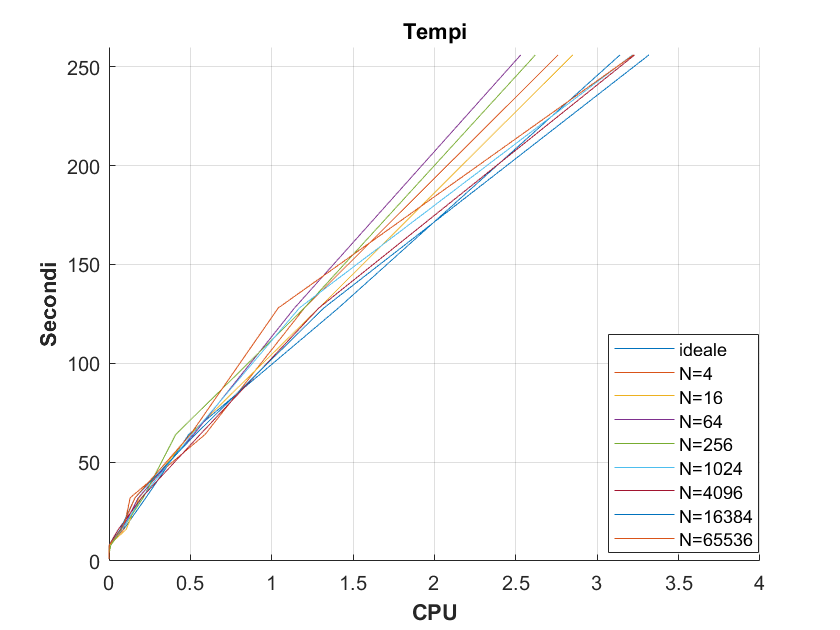

format long

%Size problema
N = [1, 4, 16, 64, 256, 1024, 4096, 16384, 65536];

%Numero processori
cpu = [1, 2, 4, 8, 16, 32, 64, 128, 256];

%Vettori dei tempi di esecuzione dell'algoritmo (τ)
t1 = [0.000001, 0.000005, 0.000019, 0.0000016, 0.089686, 0.226548, 0.490117, 1.409912, 3.139867]; 
t4 = [0.000001, 0.000011, 0.000015, 0.002613, 0.089779, 0.129935, 0.590096, 1.200898, 2.759386]; 
t16 = [0.000002, 0.000012, 0.000015, 0.000067, 0.105505, 0.184393, 0.498763, 1.289974, 2.849856]; 
t64 = [0.000002, 0.000012, 0.000019, 0.011402, 0.07988, 0.179952, 0.519872, 1.139997, 2.529788]; 
t256 = [0.000005, 0.000006, 0.000011, 0.011402, 0.079927, 0.209921, 0.410003, 1.199876, 2.620002]; 
t1024 = [0.000009, 0.000009, 0.000022, 0.000025, 0.079999, 0.199976, 0.509997, 1.169807, 3.216928]; 
t4096 = [0.000074, 0.000042, 0.000062, 0.000288, 0.057384, 0.199924, 0.559978, 1.289416, 3.229667];
t16384 = [0.000185, 0.000316, 0.000109, 0.000187, 0.069513, 0.159987, 0.530127, 1.319995, 3.317676];
t65536 = [0.000402, 0.000375, 0.000267, 0.000631, 0.074142, 0.159915, 0.500392, 1.039916, 3.222357];

%Grafico tempi al variare delle unità processanti 
figure(1)
hold on
plot(t1, cpu, '-')
plot(t4, cpu, '-')
plot(t16, cpu, '-')
plot(t64, cpu, '-')
plot(t256, cpu, '-')
plot(t1024, cpu, '-')
plot(t4096, cpu, '-')
plot(t16384, cpu, '-')
plot(t65536, cpu, '-')
title("Tempi")
legend('ideale', 'N=4', 'N=16', 'N=64', 'N=256', 'N=1024', 'N=4096', 'N=16384', 'N=65536', 'Position', [0.72376,0.16291,0.18036,0.26667])
xlabel('CPU', FontWeight = 'bold')
ylabel('Secondi', FontWeight = 'bold')
axis([0 4 0 260])
grid on
hold off

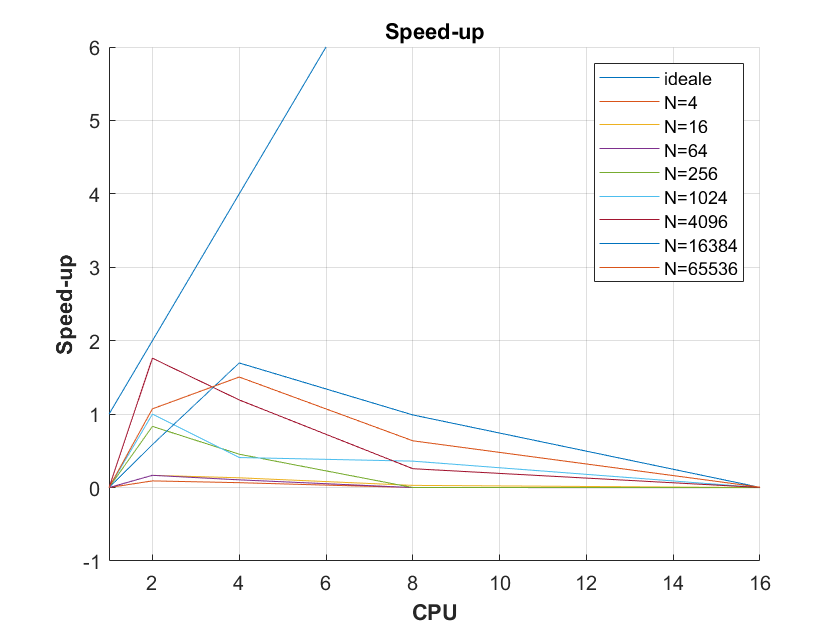

%Calcolo speed-up
s4 = [0]; 
s16 = [0]; 
s64 = [0]; 
s256 = [0]; 
s1024 = [0]; 
s4096 = [0];
s16384 = [0];
s65536 = [0];
for i= 2 : numel(N)
    s4(end + 1) = t4(1) / t4(i);
    s16(end + 1) = t16(1) / t16(i);
    s64(end + 1) = t64(1) / t64(i);
    s256(end + 1) = t256(1) / t256(i);
    s1024(end + 1) = t1024(1) / t1024(i);
    s4096(end + 1) = t4096(1) / t4096(i);
    s16384(end + 1) = t16384(1) / t16384(i);
    s65536(end + 1) = t65536(1) / t65536(i);
end

%Grafico speed-up al variare delle unità processanti
figure(2)
hold on
plot(cpu, cpu, '-')
plot(cpu, s4, '-')
plot(cpu, s16, '-')
plot(cpu, s64, '-')
plot(cpu, s256, '-')
plot(cpu, s1024,'-')
plot(cpu, s4096, '-')
plot(cpu, s16384, '-')
plot(cpu, s65536,'-')
title("Speed-up")
legend('ideale', 'N=4', 'N=16', 'N=64', 'N=256', 'N=1024', 'N=4096', 'N=16384', 'N=65536')
xlabel('CPU', FontWeight = 'bold')
ylabel('Speed-up', FontWeight = 'bold')
grid on
axis([1 16 -1 6])
hold off

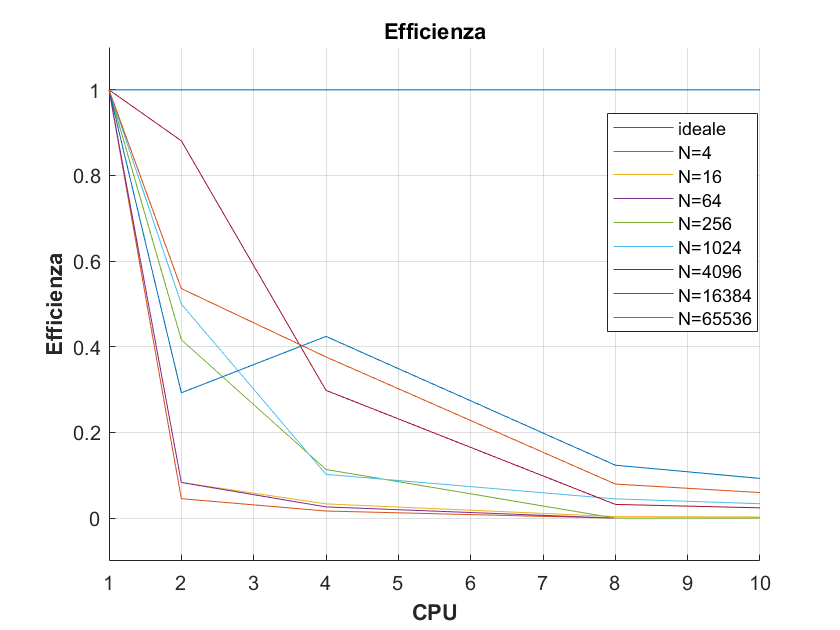

%Calcola efficienza
e1 = [1, 1, 1, 1, 1, 1, 1, 1, 1]; 
e4 = [1]; 
e16 = [1]; 
e64 = [1]; 
e256 = [1]; 
e1024 = [1]; 
e4096 = [1];
e16384 = [1];
e65536 = [1];
for i= 2 : numel(N)
    e4(end + 1) = s4(i) / cpu(i);
    e16(end + 1) = s16(i) / cpu(i);
    e64(end + 1) = s64(i) / cpu(i);
    e256(end + 1) = s256(i) / cpu(i);
    e1024(end + 1) = s1024(i) / cpu(i);
    e4096(end + 1) = s4096(i) / cpu(i);
    e16384(end + 1) = s16384(i) / cpu(i);
    e65536(end + 1) = s65536(i) / cpu(i);
end

%Grafico efficienza al variare delle unità processanti 
figure(3)
hold on
plot(cpu, e1, '-')
plot(cpu, e4, '-')
plot(cpu, e16, '-')
plot(cpu, e64, '-')
plot(cpu, e256, '-')
plot(cpu, e1024,'-')
plot(cpu, e4096, '-')
plot(cpu, e16384, '-')
plot(cpu, e65536,'-')
title("Efficienza")
legend('ideale', 'N=4', 'N=16', 'N=64', 'N=256', 'N=1024', 'N=4096', 'N=16384', 'N=65536')
xlabel('CPU', FontWeight = 'bold')
ylabel('Efficienza', FontWeight = 'bold')
axis([1 10 -0.1 1.1])
grid on
hold off

legend("Position",[0.72321,0.47302,0.17917,0.34762])